# Code to Run on 4/30

clc                     % clear command window
clear                   % clear MATLAB workspace
% profile on            % profile used to time each segment of code

## **Set up robot control system** ( code that runs once )

% Set up Raspberry Pi
disp('note: It takes a 10 seconds or so to download code to Raspberry PI '); 
[robotPi, blinkLED]= RaspPiSetup()

% Turn on board LED on and off to signal program has started 
Blink(robotPi,blinkLED,10);
disp('Warning! Robot Rover Active! ');

% Set up servos, PiCam, and QWIIC analog input
[roverServos, roverJoy] = ServoSetup(robotPi)
[robotCam] = PiCamSetup(robotPi)
[rawRangeData] = QWIICInputSetup(robotPi)
% TODO: GPS SETUP
[neo] = GPSSetup(robotPi)

**CREATE GLOBAL VARIABLES**

sampleTime = 0.5;                                  % Sample time [s]
t = 0:sampleTime:100;                              % Time array
r = rateControl(1/sampleTime);                     % reset control loop  rate
reset(r);                                          % reset loop time to zero
GPSToGridRatio = 2; % CHANGE THIS

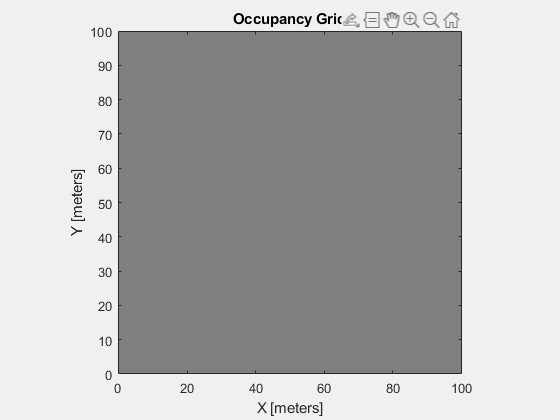


% Create an empty map of the same dimensions as the test track map                      
roverOccupancyGrid = occupancyMap(100,100);  % Make empty map the same size
% Create free floating figure (Rover occupancy grid)
figureRoverOccupancy = figure('name', 'RoverOccupancyGrid', 'NumberTitle', 'off', 'Visible', 'on');
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid);         % Show the map in figure window

t = 1
while t < 100
    % start rover
    DriveRover(robotPi,roverServos,direction,speed);  
    GPSGetLocation(roverOccupancyGrid,neo)
    MissionOneSense(roverOcupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1,adcDevice2, robotCam, roverJoy)
    t = t + 1;
end

%stop rover
DriveRover(robotPi,roverServos,50,50);  

function[roverOccupancyGrid, roverBearing, roverLocation, gate_number] = GPSGetLocation(roverOccupancyGrid,neo) % this will be provided from canvas
basic_data = neo.getBasic();
% roverX = basic_data.longitude
% roverY = basic_data.lattitude
roverLocation = [basic_data.longitude basic_data.lattitude];
roverBearing = basic_data.heading;
% add code for making the gate number thing work
gate_number = 1;
% plotting rover position on occupancy grid through conversion
[gridIndex] = GPSCoordToGridIndex(GPSCoordinate);
pvalues = 0.6; % this is the value for the rover position
updateOccupancy(roverOccupancyGrid,[gridIndex(1) gridIndex(2)],pvalues);
end

function [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, roverBearing, roverLocation, adcDevice1, adcDevice2)
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawRangeData = [rawRangeData2,rawRangeData1]; 
     angles = [1 2 3 4 5; -pi/3 -pi/6 0 pi/6 pi/3]; % chagne this later     
     threshold = 40;
     for i = 1:5
        % voltage to distance     
        distance = (rawRangeData(i,:) - 2.805)/(-0.03316);
        if distance < threshold
            [obstaclePosX, obstaclePosY] = findGridPos(angles(i), distance, roverLocation);
            updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
        end   
     end  
end



function [obstaclePosX, obstaclePosY] = findGridPos(omega, distance, roverLocation) % Helper function for sonar / IR
    if omega < 0
            omega = 360+omega;
        elseif omega > 360
            omega = omega-360;
        end
        quo = omega/90;
        modulo = mod(omega,90);
        if floor(quo) == 0 % Quadrant I
            obstaclePosX = roverLocation(0) + (distance*cosd(modulo))
            obstaclePosY = roverLocation(1) + (distance*sind(modulo))
        elseif floor(quo) == 1 % Quadrant IV
            obstaclePosX = roverLocation(0) + (distance*cosd(modulo))
            obstaclePosY = roverLocation(1) - (distance*sind(modulo))
        elseif floor(quo) == 2 % Quadrant III
            obstaclePosX = roverLocation(0) - (distance*cosd(modulo))
            obstaclePosY = roverLocation(1) - (distance*sind(modulo))
        elseif floor(quo) == 3 % Quadrant IV
            obstaclePosX = roverLocation(0) - (distance*cosd(modulo))
            obstaclePosY = roverLocation(1) + (distance*sind(modulo))
        end
end

function [roverOccupancyGrid] = SonarRange(roverOccupancyGrid, figureRoverOccupancy, headBearing, roverLocation, adcDevice1) % fill in other variables
% Mark obstacles based on the positions on the grid

    % Sonar calibration, covert voltage data into distance measurement (cm)
    distanceLeft = (rawRangeData(1, 1)-0.01063)/0.01584; 
    distanceRight = (rawRangeData(2, 1)-0.01063)/0.01584;
    
    % If measured distance is within some threshold, mark it as an obstacle
    % on the occupancy grid
    threshold = 5;
    if distanceLeft < threshold
        omegaLeft = headBearing-90;
        [obstaclePosX, obstaclePosY] = findGridPos(omegaLeft, distanceLeft, roverLocation)
        updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
        
    end
    if distanceRight < threshold 
        omegaRight = headBearing-90;
        [obstaclePosX, obstaclePosY] = findGridPos(omegaRight, distanceRight, roverLocation)
        updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
    end
end



function[roverOcupancyGrid] = MissionOneSense(roverOcupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1,adcDevice2, robotCam,roverJoy)
%% TODO for sonar function, headBearing == roverBearing + (panAngle converted to global bearing)
    
    joystickControl=1
    while joystickControl == 1
        % Use joystick to move rover head, Y + enter when ready to sense
        while 1
            [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
            DrivePanTilt(panAngle, tiltAngle)
            stop=input('Ready to sense? type Y then hit enter ','s');
            if stop == 'Y'
                break
            end
        end
        % Call all the sense functions related to Mission 1
        [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1, adcDevice2) % fill in other variable
%         [roverOcupancyGrid] = PiCamLaser(roverOcupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, robotCam) % laser for obstacle avoidance
%         [roverOcupancyGrid] = PiCamObstacles(roverOcupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, robotCam) % color masking for obstacles
        [roverOccupancyGrid] =  SonarRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing+panAngle, roverLocation, adcDevice1) % fill in other variables
       
        figure(figureRoverOccupancy);     % Show updated occupancy grid
            hold on;
            show(roverOccupancyGrid);
            grid on;
            grid minor;
            hold off;
        
        joystickControl=input('Keep sensing? (0-1)');
    end
end


function [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
% this function polls USB joystick and returns x position 
% for Rover steering angle and y position for Rover velocity
    stickX = axis(roverJoy, 1);     % X-axis is joystick axis 1 (-1 to 1)
    stickY = axis(roverJoy, 2);     % Y-axis is joystick axis 2 (-1 to 1)
    panAngle = 50 + (10 * stickX);  % scale X for servo with pulse centered at 50
    tiltAngle = 50 + (-10 * stickY);  % scale Y for servo with pulse centered at 50
end

function rawRangeDataN = SENSE_ADC(adcDeviceN)
     % read ADC1 Pin 0-4 voltage
    rawRangeDataN = [adcDeviceN.readVoltage(0), adcDeviceN.readVoltage(1), ...
                adcDeviceN.readVoltage(2), adcDeviceN.readVoltage(3)]; 
end

**THINK FUNCTIONS**


function [gridIndex] = GPSCoordToGridIndex(GPSCoordinate)
    xgrid = round(GPSCoordinate(1) / GPSToGridRatio);
    ygrid = round(GPSCoordinate(2) / GPSToGridRatio);
    gridIndex = [xgrid ygrid];    
end

**ACT FUNCTIONS**

function [] = DrivePanTilt(panAngle, tiltAngle)
     roverServos.setServoPWM(4,panAngle);    % commands panning servo
     roverServos.setServoPWM(5,tiltAngle);   % commands tilting servo
end

function [] = DriveRover(robotPi,roverServos,direction,speed)
     roverServos.setServoPWM(1,direction);    % commands steering servo
     roverServos.setServoPWM(2,speed);    % commands drive speed controller
end
